%This script checks some of the data in Nienhuis et al. 2020: Fig.3, Table1, Aqua_vs_GSW 
%It uses GlobalDeltaData.mat delta database from https://osf.io/s28qb/ published by Nienhuis et al., 2020 (GlobalDeltaData.mat)
% Global_deltas_area.csv is needed when comparink Aqua data with GSW(pekel)

load GlobalDeltaData.mat; 

%Check data similarity: Vs original reported in paper
sum(ee.net_aqua) % 54

ans = 52.8968

sum(ee.dep_aqua) % 181

ans = 181.4453

sum(ee.ero_aqua) %-127

ans = -128.5485

%=> very similar data

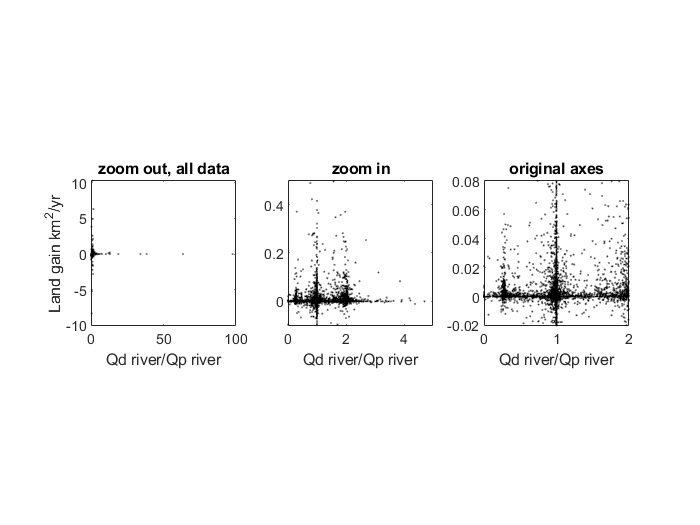

% Plots of Fig.3a with different zoom levels
clf
figure(1)

subplot(1,3,1)
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.1,'.','k')
xlim([0 100])
xlabel 'Qd river/Qp river'
ylabel 'Land gain km^2/yr'
title 'zoom out, all data'
axis square
box on

subplot(1,3,2)
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.1,'.','k')
xlim([0 5])
ylim([-0.1 0.5])
xlabel 'Qd river/Qp river'
%ylabel 'Land gain km^2/yr'
title 'zoom in'
axis square
box on

subplot(1,3,3)
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qd river/Qp river'
%ylabel 'Land gain km^2/yr'
title 'original axes'
axis square
box on
set(gcf,'color','white')


%Check how much of the data is shown in zoomed figure
log_zoomx = QRiver_dist./QRiver_prist < 2; %get deltas shown on x axis
log_zoomy = ee.net_aqua < 0.08 & ee.net_aqua > -0.02; %get deltas shown on y axis

%Get change (km^2/yr) not shown in Fig. 3a
10848 - sum(log_zoomx) % No of deltas not shown on x = 843

ans = 843

10848 - sum(log_zoomy) % No of deltas not shown on y axis = 360

ans = 360

52.9 - sum(ee.net_aqua(log_zoomy)) %-> How much change not shown overall: About half (25 km^2)

ans = 24.9386

52.9 - sum(ee.net_aqua(log_zoomy & log_zoomx)) %-> How much change not shown overall: More than half (29km^2)

ans = 29.1808

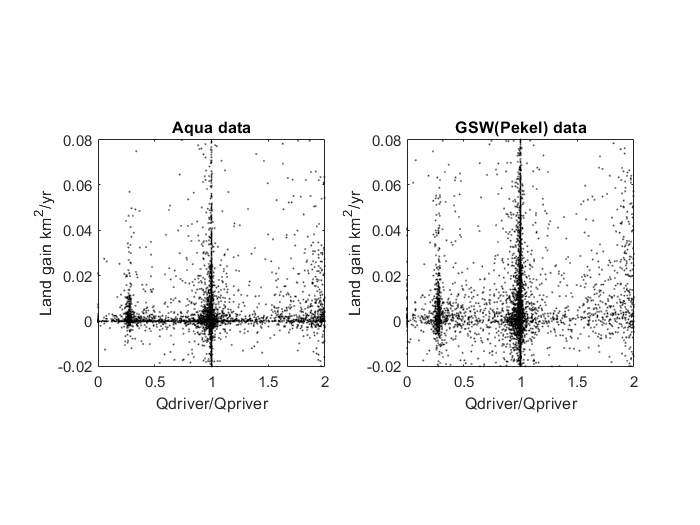

%Aqua vs GSW(pekel)
clf
figure(2)

subplot(1,2,1)
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdriver/Qpriver'
ylabel 'Land gain km^2/yr'
title 'Aqua data'
axis square
box on

subplot(1,2,2)
scatter(QRiver_dist./QRiver_prist, ee.net_pekel, 0.05,'.','k')
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdriver/Qpriver'
ylabel 'Land gain km^2/yr'
title 'GSW(Pekel) data'
axis square
box on
set(gcf,'color','white')


%Scatter from Fig.3a looks a lot like GSW(pekel) and not Aqua



%Check Bin averages from fig. 3a

edges = 0:0.1:2;
[~,~,bins] = histcounts (QRiver_dist./QRiver_prist, edges);

%Get bin averages for all data:
%Aqua
for i = 1:numel(edges)
  ee_bin_means_aqua(:,i) = mean(ee.net_aqua(bins==i,:))';
end

%GSW
for i = 1:numel(edges)
  ee_bin_means_pekel(:,i) = mean(ee.net_pekel(bins==i,:))';
end

%Get bin averages for the data windows shown in original Fig. 3a
net_aqua_cut = ee.net_aqua;
net_aqua_cut(net_aqua_cut > 0.5)= NaN; net_aqua_cut(net_aqua_cut < -0.2) = NaN;
for i = 1:numel(edges)
  ee_bin_cutmeans_aqua(:,i) = nanmean(net_aqua_cut(bins==i))';
end

net_pekel_cut = ee.net_pekel;
net_pekel_cut(net_pekel_cut > 0.08) = NaN; net_pekel_cut(net_pekel_cut < -0.02) = NaN;
for i = 1:numel(edges)
  ee_bin_cutmeans_pekel(:,i) = nanmean(net_pekel_cut(bins==i))';
end


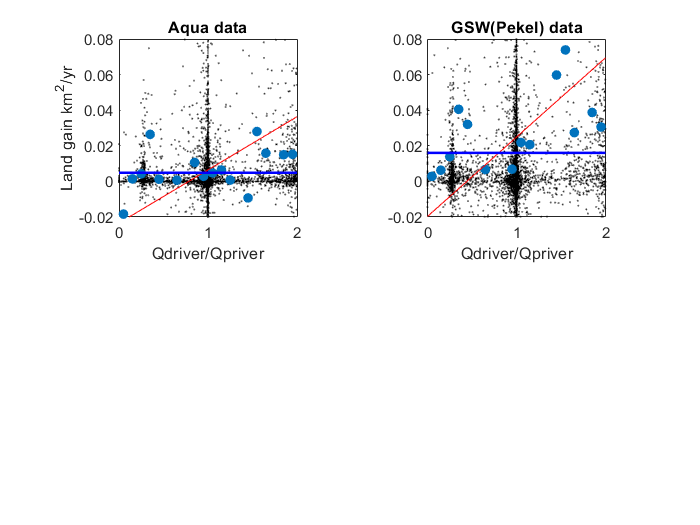

%Aqua vs GSW(pekel) with bin means
clf
figure(4)

%Cut bin means
% subplot(2,2,1)
% scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
% hold on
% plot(edges+0.05, ee_bin_cutmeans_aqua,'.', 'MarkerSize',20)
% xlim([0 2])
% ylim([-0.02 0.08])
% %xlabel 'Qdriver/Qpriver'
% ylabel 'Land gain km^2/yr'
% title 'Aqua data'
% axis square
% box on
% 
% subplot(2,2,2)
% scatter(QRiver_dist./QRiver_prist, ee.net_pekel, 0.05,'.','k')
% hold on
% plot(edges+0.05, ee_bin_cutmeans_pekel,'.', 'MarkerSize',20)
% xlim([0 2])
% ylim([-0.02 0.08])
% %xlabel 'Qdriver/Qpriver'
% %ylabel 'Land gain km^2/yr'
% title 'GSW(Pekel) data'
% axis square
% box on

%All data (y scale) bin means
ax1 = subplot(2,2,1);
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
hold on
plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax1);
h1(1).Color = 'r'; % regression only cut data bins
h1(2).Color = 'b'; % regression all data
h1(2).LineWidth = 1.5;
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdriver/Qpriver'
ylabel 'Land gain km^2/yr'
title 'Aqua data'
axis square
box on

ax2 = subplot(2,2,2);
scatter(QRiver_dist./QRiver_prist, ee.net_pekel, 0.05,'.','k')

hold on
plot(edges+0.05, ee_bin_means_pekel,'.', 'MarkerSize',20)
h2 = lsline(ax2);
h2(1).Color = 'r'; % regression only cut data bins
h2(2).Color = 'b'; % regression all data
h2(2).LineWidth = 1.5;
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdriver/Qpriver'
%ylabel 'Land gain km^2/yr'
title 'GSW(Pekel) data'
axis square
box on


% ax3 = subplot(2,2,3);
% scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
% hold on
% plot(edges2+0.05, ee_bin_means_aqua2,'.', 'MarkerSize',20)
% h3 = lsline(ax3);
% h3(1).Color = 'r'; % regression only cut data bins
% h3(2).Color = 'b'; % regression all data
% h3(2).LineWidth = 1.5;
% xlim([0 4])
% ylim([-0.06 0.15])
% xlabel 'Qdriver/Qpriver'
% ylabel 'Land gain km^2/yr'
% title 'Aqua data'
% axis square
% box on
% set(gcf,'color','white')

%%%%%%% Check if bin values are correct
Qdp = QRiver_dist./QRiver_prist;
mean(ee.net_aqua(Qdp >= 0 & Qdp < 0.1))% for bin 1

ans = -0.0184

mean(ee.net_aqua(bins == 1))

ans = -0.0184

mean(ee.net_aqua(Qdp >= 1.3 & Qdp < 1.4))% for bin 14 (outside of y axis)

ans = 0.0940

mean(ee.net_aqua(bins == 14))

ans = 0.0940

%-> graph bins are verified

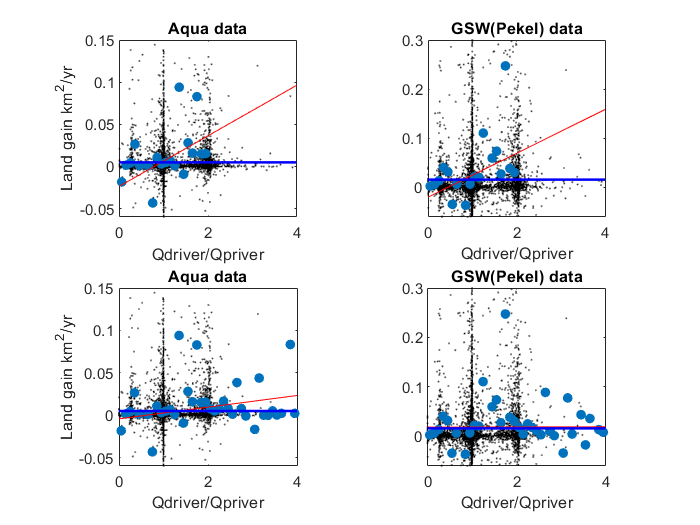

%Check Bin averages also for data not shown in fig. 3a (x axis)

%1- Keep original bins, extend zoom
clf
figure

ax1 = subplot(2,2,1);
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
hold on
plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax1);
h1(1).Color = 'r'; % regression only cut data bins
h1(2).Color = 'b'; % regression all data
h1(2).LineWidth = 1.5;
xlim([0 4])
ylim([-0.06 0.15])
xlabel 'Qdriver/Qpriver'
ylabel 'Land gain km^2/yr'
title 'Aqua data'
axis square
box on

ax2 = subplot(2,2,2);
scatter(QRiver_dist./QRiver_prist, ee.net_pekel, 0.05,'.','k')

hold on
plot(edges+0.05, ee_bin_means_pekel,'.', 'MarkerSize',20)
h2 = lsline(ax2);
h2(1).Color = 'r'; % regression only cut data bins
h2(2).Color = 'b'; % regression all data
h2(2).LineWidth = 1.5;
xlim([0 4])
ylim([-0.06 0.3])
xlabel 'Qdriver/Qpriver'
%ylabel 'Land gain km^2/yr'
title 'GSW(Pekel) data'
axis square
box on

%2 - Get more bins on x axis
edges2 = 0:0.1:4; %sets min and max value for edge bins
[~,~,bins2] = histcounts (QRiver_dist./QRiver_prist, edges2);

%Get bin averages for data on extended x axis:
%Aqua
ee_bin_means_aqua2 = [];
for i = 1:numel(edges2)
  ee_bin_means_aqua2(:,i) = mean(ee.net_aqua(bins2==i,:))';
end

%GSW
ee_bin_means_pekel2 = [];
for i = 1:numel(edges2)
    
  ee_bin_means_pekel2(:,i) = mean(ee.net_pekel(bins2==i,:))';
end

ax1 = subplot(2,2,3);
scatter(QRiver_dist./QRiver_prist, ee.net_aqua, 0.05,'.','k')
hold on
plot(edges2+0.05, ee_bin_means_aqua2,'.', 'MarkerSize',20)
h1 = lsline(ax1);
h1(1).Color = 'r'; % regression only cut data bins
h1(2).Color = 'b'; % regression all data
h1(2).LineWidth = 1.5;
xlim([0 4])
ylim([-0.06 0.15])
xlabel 'Qdriver/Qpriver'
ylabel 'Land gain km^2/yr'
title 'Aqua data'
axis square
box on

ax2 = subplot(2,2,4);
scatter(QRiver_dist./QRiver_prist, ee.net_pekel, 0.05,'.','k')

hold on
plot(edges2+0.05, ee_bin_means_pekel2,'.', 'MarkerSize',20)
h2 = lsline(ax2);
h2(1).Color = 'r'; % regression only cut data bins
h2(2).Color = 'b'; % regression all data
h2(2).LineWidth = 1.5;
xlim([0 4])
ylim([-0.06 0.3])
xlabel 'Qdriver/Qpriver'
%ylabel 'Land gain km^2/yr'
title 'GSW(Pekel) data'
axis square
box on
set(gcf,'color','white')

%test R_squared for cut data bins
regressioncut_aqua1 = fitlm((1:21),ee_bin_means_aqua) %R^2 = 0.188

regressioncut_aqua1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    _______    ________

    (Intercept)    -0.024905     0.017559    -1.4184     0.17315
    x1             0.0029882    0.0014658     2.0387    0.056448


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0378
R-squared: 0.188,  Adjusted R-Squared 0.142
F-statistic vs. constant model: 4.16, p-value = 0.0564

NRMSE_bin = 0.037./mean(ee_bin_means_aqua(1:20))

NRMSE_bin = 5.7182

NRMSE_sd = 0.037./std(ee_bin_means_aqua(1:20))
regressioncut_pekel1 = fitlm((1:21),ee_bin_means_pekel) %R^2 = 0.138

regressioncut_pekel1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    ________    _______

    (Intercept)     -0.02189      0.03144    -0.69624    0.49517
    x1             0.0044562    0.0026245      1.6979    0.10675


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0677
R-squared: 0.138,  Adjusted R-Squared 0.0902
F-statistic vs. constant model: 2.88, p-value = 0.107

%=> Similar to reported in paper (0.16, or 16%).

%test R_squared for extended data bins (Qd/Qp max 4)
regressioncut_aqua2 = fitlm((1:length(edges2)),ee_bin_means_aqua2) %R^2 = 0.057

regressioncut_aqua2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat      pValue 
                   __________    __________    ________    _______

    (Intercept)    -0.0046825      0.010623    -0.44079      0.662
    x1             0.00068777    0.00046543      1.4777    0.14818


Number of observations: 38, Error degrees of freedom: 36
Root Mean Squared Error: 0.0326
R-squared: 0.0572,  Adjusted R-Squared 0.031
F-statistic vs. constant model: 2.18, p-value = 0.148

regressioncut_pekel2 = fitlm((1:length(edges2)),ee_bin_means_pekel2) %R^2 = 0.06

regressioncut_pekel2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat      pValue 
                   __________    __________    ________    _______

    (Intercept)      0.018546      0.019061     0.97299    0.33705
    x1             1.8768e-05    0.00083512    0.022473    0.98219


Number of observations: 38, Error degrees of freedom: 36
Root Mean Squared Error: 0.0585
R-squared: 1.4e-05,  Adjusted R-Squared -0.0278
F-statistic vs. constant model: 0.000505, p-value = 0.982

%=> a lot lower

%test R_squared for all data
logq = QRiver_dist./QRiver_prist<2;
regression_aqua3 = fitlm(QRiver_dist./QRiver_prist, ee.net_aqua)

regression_aqua3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat       pValue  
                   ___________    _________    _________    _________

    (Intercept)      0.0048767    0.0016884       2.8883    0.0038813
    x1             -2.7412e-13    1.523e-11    -0.017998      0.98564


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.176
R-squared: 2.99e-08,  Adjusted R-Squared -9.22e-05
F-statistic vs. constant model: 0.000324, p-value = 0.986

NRMSEall_mean = 0.176./mean(ee.net_aqua)

NRMSEall_mean = 36.0938

NRMSEall_sd = 0.176./std(ee.net_aqua)

NRMSEall_sd = 1.0010

regression_aqua4 = fitlm(QRiver_dist(logq)./QRiver_prist(logq), ee.net_aqua(logq))%Qdp max2(all)

regression_aqua4 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)    -0.011985    0.0059138    -2.0266     0.042727
    x1              0.017009    0.0057584     2.9538    0.0031462


Number of observations: 10005, Error degrees of freedom: 10003
Root Mean Squared Error: 0.183
R-squared: 0.000871,  Adjusted R-Squared 0.000772
F-statistic vs. constant model: 8.72, p-value = 0.00315

regression_pekel3 = fitlm(QRiver_dist./QRiver_prist, ee.net_pekel)

regression_pekel3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    ________    _________

    (Intercept)     0.016018     0.0053793      2.9777    0.0029102
    x1             1.592e-12    4.8524e-11    0.032809      0.97383


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.56
R-squared: 9.92e-08,  Adjusted R-Squared -9.21e-05
F-statistic vs. constant model: 0.00108, p-value = 0.974

%R2 basically 0, huge RMSE



%Check fluvial decrease/increase data from Table 1:

Fluvial_decrease = (QRiver_dist./QRiver_prist) < 0.5;
Fluvial_increase = (QRiver_dist./QRiver_prist) > 1.5;

%Check if sum of deltas for each class similar with the ones reported
sum(Fluvial_decrease)%970 in paper (Table 1)

ans = 964

sum(Fluvial_increase)%1478 in paper

ans = 1473


                                  %Original values (Table 1)) vs New values
sum(ee.net_aqua(Fluvial_decrease))%-12 km2 vs 5

ans = 5.0342

sum(ee.dep_aqua(Fluvial_decrease))% 15     vs 12

ans = 12.1704

sum(ee.ero_aqua(Fluvial_decrease))%-27     vs-7

ans = -7.1362

% Fluvial decrease much different for erosion

sum(QRiver_prist(Fluvial_decrease)) % 9.2e+04

ans = 9.7508e+04

sum(QRiver_dist(Fluvial_decrease))  % 1.8e+04

ans = 2.0843e+04


sum(ee.net_aqua(Fluvial_increase))% 25     vs 23

ans = 23.2550

sum(ee.dep_aqua(Fluvial_increase))% 36     vs 33

ans = 32.9491

sum(ee.ero_aqua(Fluvial_increase))%-11     -9.7

ans = -9.6941

% Fluvial increase similar
sum(QRiver_prist(Fluvial_increase)) % 3.1e+04

ans = 2.7136e+04

sum(QRiver_dist(Fluvial_increase))  % 7.6e+04

ans = 4.9405e+04


%Conclusion: Significant departure for
% sum of Fluvial decrease = -20km^2/yr difference! 
% Not explainable from dataset variability

%Now check wave reworking
%Wave reworking defined as a fluvial sediment flux decrease greater than 50% and Qwave > Qtide.
Wave_revorking = Fluvial_decrease & QWave > QTide;
sum(Wave_revorking) %736 in Table 1

ans = 821


sum(ee.net_aqua(Wave_revorking)) %-13   vs 1

ans = 1.0661

sum(ee.dep_aqua(Wave_revorking)) % 12   vs 6

ans = 5.7253

sum(ee.ero_aqua(Wave_revorking)) %-25   vs -5

ans = -4.6591

%reported values much different

sum(QRiver_prist(Wave_revorking)) % 5e+04

ans = 5.5843e+04

sum(QRiver_dist(Wave_revorking))  % 0.8e+04

ans = 7.1238e+03

%sum of discharges similar to what shown in table 1 => wave reworking
%deltas resonably well identified



%Compare Aqua and GSW

sum(ee.net_aqua) % 54

ans = 52.8968

sum(ee.net_pekel) % 173.8

ans = 173.7974

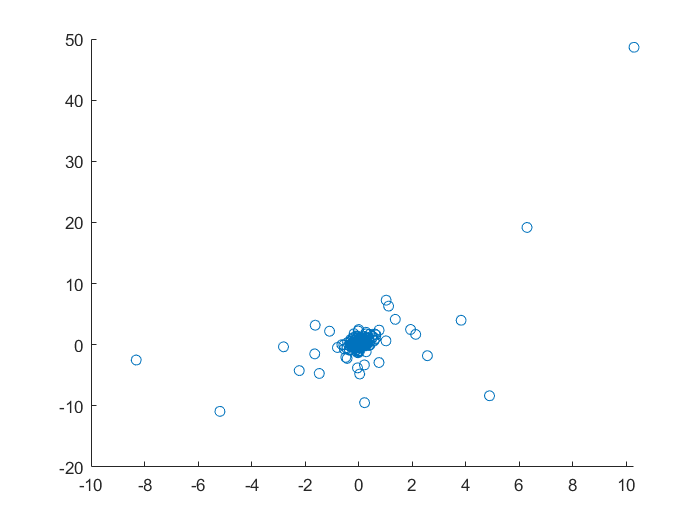

%compare clean data
clf
figure
scatter(ee.net_aqua, ee.net_pekel)

regression_scatter = fitlm(ee.net_aqua, ee.net_pekel)

regression_scatter = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat     pValue 
                   _________    _________    ______    _______

    (Intercept)    0.0054673    0.0039485    1.3847    0.16619
    x1                2.1644     0.022449    96.412          0


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.411
R-squared: 0.462,  Adjusted R-Squared 0.461
F-statistic vs. constant model: 9.3e+03, p-value = 0

%data scales on different orders of magnitude based on buffer size

% 1 - divide by deltaradius
%scatter(ee.net_aqua./DeltaRadius, ee.net_pekel./DeltaRadius)
%regression_scatter_radius = fitlm(ee.net_aqua./DeltaRadius, ee.net_pekel./DeltaRadius)
%ylim ([-30 50])
%xlim ([-30 50])
%xlabel 'GSW(pekel)'
%ylabel 'aqua'

% 2 - Eliminating the dependant variable -> divide by buffer area 
Buffer_area=xlsread('Global_deltas_area.csv'); %load buffer area with basin id
Buffer_area_km = Buffer_area(:,4);
[~,idarea] = ismember(BasinID2, Buffer_area(:,2));

clf
figure
scatter(ee.net_aqua./Buffer_area_km(idarea), ee.net_pekel./Buffer_area_km(idarea))
h = lsline

h =   Line (lsline) with properties:

              Color: [0.7500 0.7500 0.7500]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0400 0.0300]
              YData: [-0.0559 0.0424]
              ZData: [1×0 double]

  Show all properties


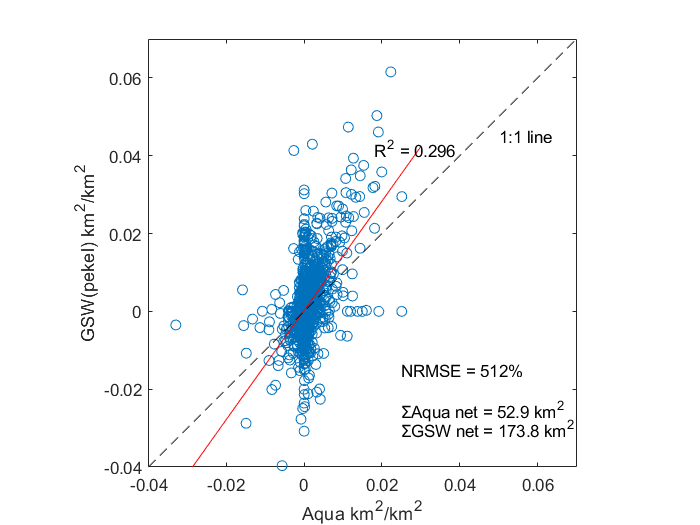

h.Color = 'r';
ylim ([-0.04 0.07])
xlim ([-0.04 0.07])
line ([-0.04 0.07], [-0.04 0.07],'Color','k','LineStyle','--')
text(0.05,0.045,'1:1 line')
text(0.018,0.042,'R^2 = 0.296')
text(0.025,-0.025,'ΣAqua net = 52.9 km^2')
text(0.025,-0.03,'ΣGSW net = 173.8 km^2')
xlabel 'Aqua km^2/km^2'
ylabel 'GSW(pekel) km^2/km^2'
axis square
box on
NRMSE_mean = 0.00291./mean(ee.net_pekel./Buffer_area_km(idarea))
NRMSE_sd = 0.00291./std(ee.net_pekel./Buffer_area_km(idarea))
text(0.025,-0.015,'NRMSE = 5.12')
set(gcf,'color','white')


regression_scatter_area = fitlm(ee.net_aqua./Buffer_area_km(idarea), ee.net_pekel./Buffer_area_km(idarea))

regression_scatter_area = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)    0.00027917    2.8245e-05    9.8837    6.1248e-23
    x1                 1.4033       0.02077    67.564             0


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.00291
R-squared: 0.296,  Adjusted R-Squared 0.296
F-statistic vs. constant model: 4.56e+03, p-value = 0



% %plot([-0.04 0.07], [-0.04 0.07])
% plot(regression_scatter_area)
% ylim ([-0.04 0.07])
% xlim ([-0.04 0.07])
% xlabel 'GSW(pekel)'
% ylabel 'aqua'
